clear;
clf;
T = readtable('aeda_data.xls');

T = T(2:end,:);

Data = struct();

Data.EDSS = T{:,2};
Data.Skupina = T{:,3};
Data.Vek = T{:,4};
Data.DelkaNohy = T{:,5};

Data.Rychlost.Normal = T{:,6};
Data.Rychlost.Rychla = T{:,7};

Data.DelkaKroku.Normal.Leva  = T{:,8};
Data.DelkaKroku.Rychla.Leva  = T{:,9};
Data.DelkaKroku.Normal.Prava = T{:,10};
Data.DelkaKroku.Rychla.Prava = T{:,11};

Data.CasKroku.Normal.Leva  = T{:,12};
Data.CasKroku.Rychla.Leva  = T{:,13};
Data.CasKroku.Normal.Prava = T{:,14};
Data.CasKroku.Rychla.Prava = T{:,15};

Data.Stoj.Normal.Leva  = T{:,16};
Data.Stoj.Rychla.Leva  = T{:,17};
Data.Stoj.Normal.Prava = T{:,18};
Data.Stoj.Rychla.Prava = T{:,19};

Data.SirkaBaze.Normal = T{:,20};
Data.SirkaBaze.Rychla = T{:,21};

Data.Variabilita.Delka.Normal.Leva  = T{:,22};
Data.Variabilita.Delka.Rychla.Leva  = T{:,23};
Data.Variabilita.Delka.Normal.Prava = T{:,24};
Data.Variabilita.Delka.Rychla.Prava = T{:,25};

Data.Variabilita.Cas.Normal.Leva  = T{:,26};
Data.Variabilita.Cas.Rychla.Leva  = T{:,27};
Data.Variabilita.Cas.Normal.Prava = T{:,28};
Data.Variabilita.Cas.Rychla.Prava = T{:,29};

Data.Variabilita.Stoj.Normal.Leva  = T{:,30};
Data.Variabilita.Stoj.Rychla.Leva  = T{:,31};
Data.Variabilita.Stoj.Normal.Prava = T{:,32};
Data.Variabilita.Stoj.Rychla.Prava = T{:,33};

# **BOXPLOTS PROMĚNNÉ VS. SKUPINY**

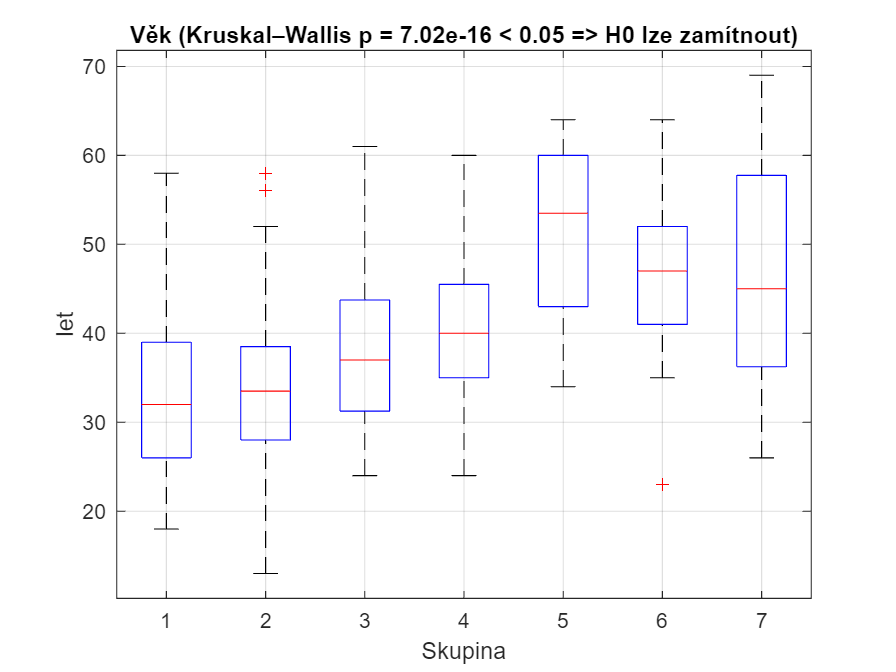

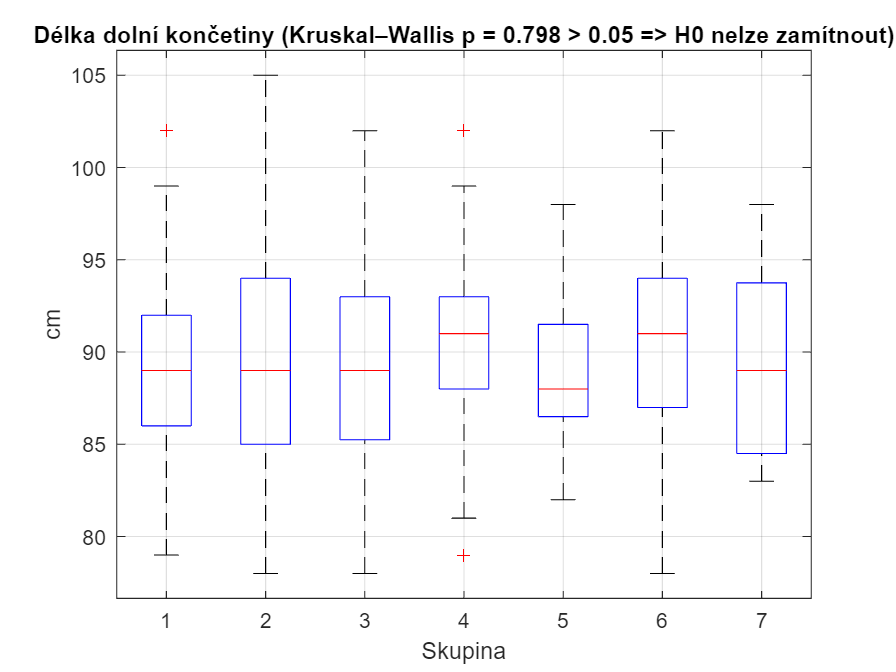

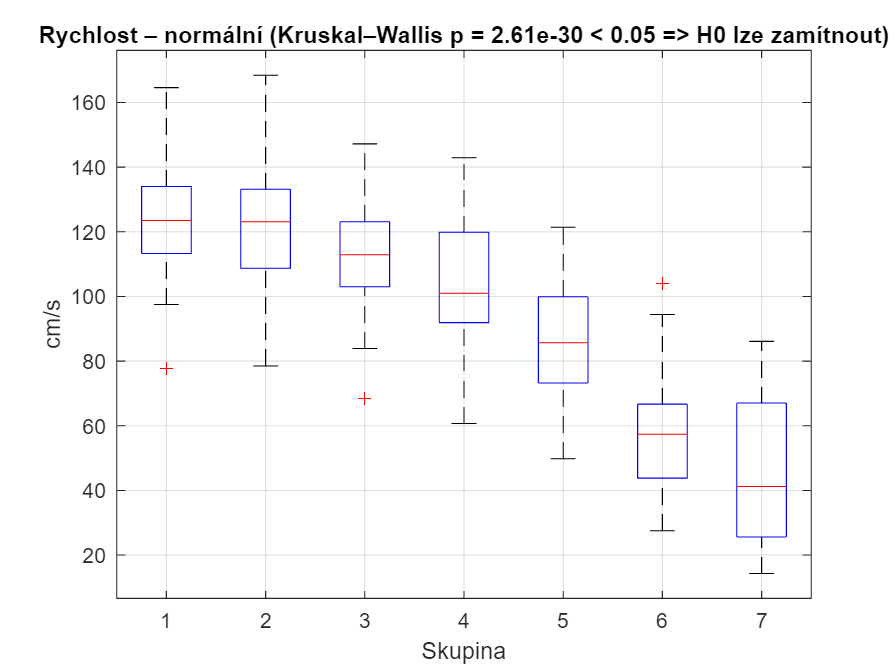

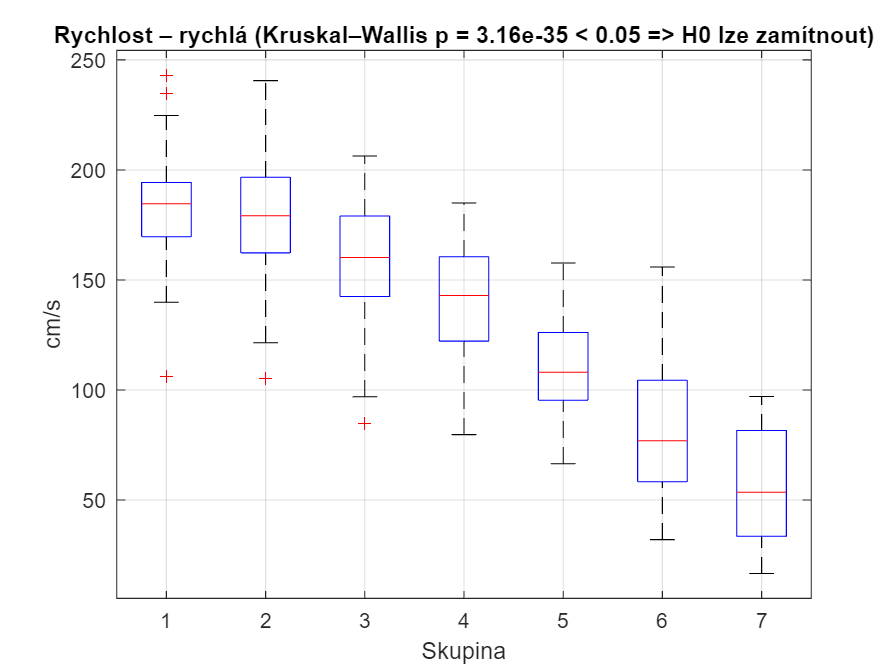

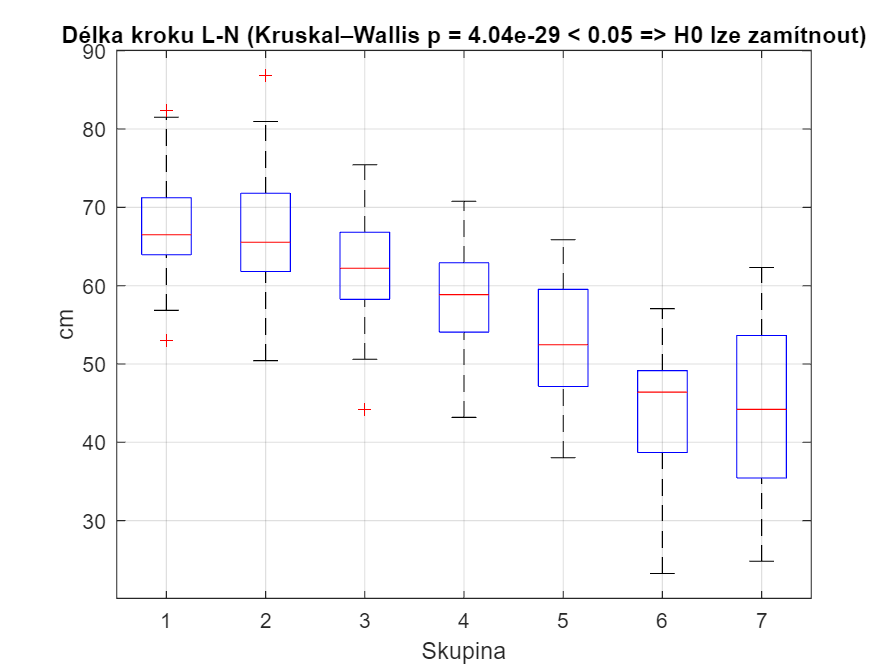

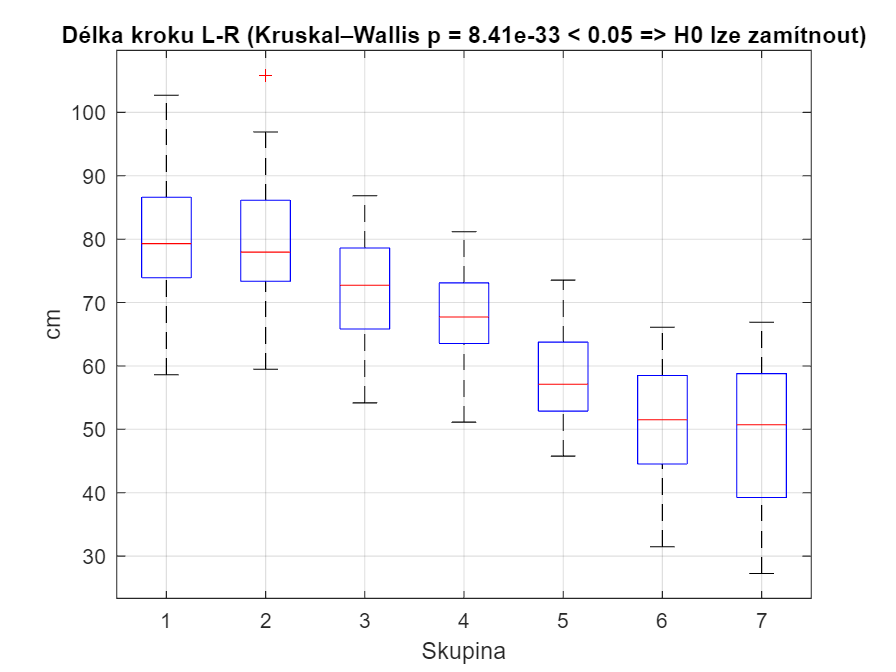

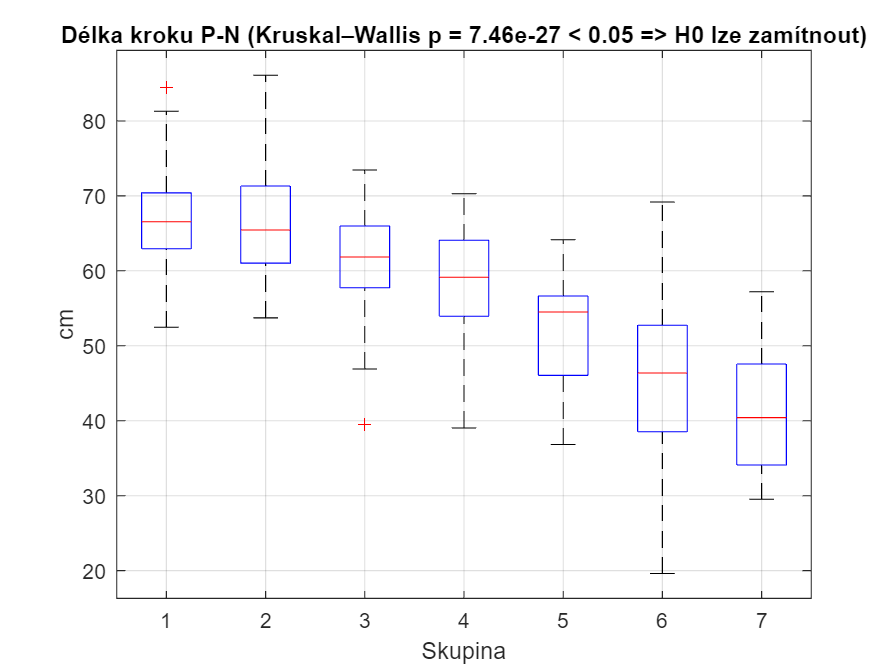

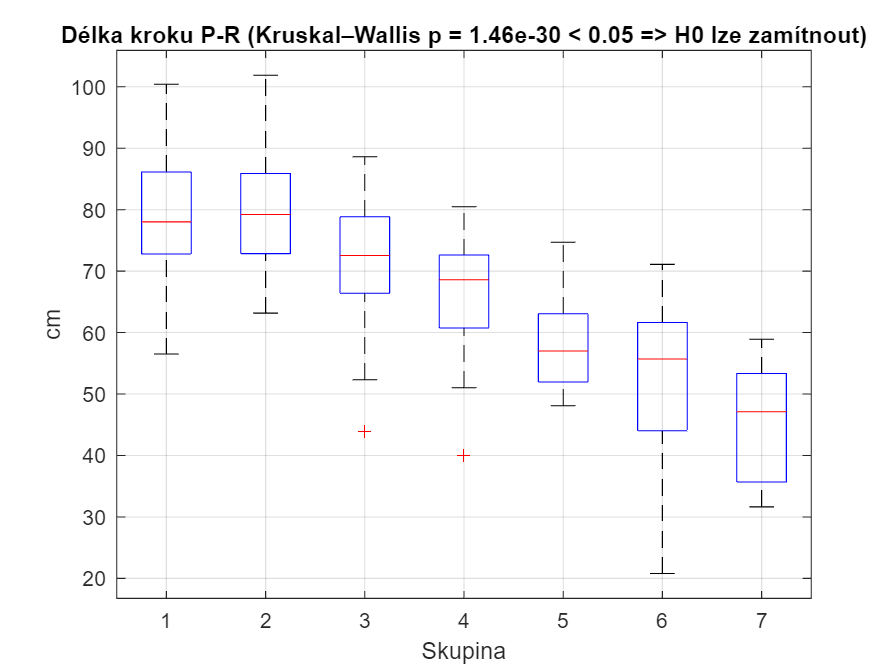

vars = {
    'Vek',       'Věk', 'let'
    'DelkaNohy',       'Délka dolní končetiny',   'cm'
    'Rychlost.Normal',       'Rychlost – normální', 'cm/s'
    'Rychlost.Rychla',       'Rychlost – rychlá',   'cm/s'
    'DelkaKroku.Normal.Leva','Délka kroku L-N',     'cm'
    'DelkaKroku.Rychla.Leva','Délka kroku L-R',     'cm'
    'DelkaKroku.Normal.Prava','Délka kroku P-N',    'cm'
    'DelkaKroku.Rychla.Prava','Délka kroku P-R',    'cm'
    'CasKroku.Normal.Leva', 'Čas kroku L-N',        's'
    'CasKroku.Rychla.Leva', 'Čas kroku L-R',        's'
    'CasKroku.Normal.Prava','Čas kroku P-N',        's'
    'CasKroku.Rychla.Prava','Čas kroku P-R',        's'
    'Stoj.Normal.Leva', 'Čas stoje na obou končetinách (Double support time) L-N',        '%'
    'Stoj.Rychla.Leva', 'Čas stoje na obou končetinách (Double support time) L-R',        '%'
    'Stoj.Normal.Prava','Čas stoje na obou končetinách (Double support time) P-N',        '%'
    'Stoj.Rychla.Prava','Čas stoje na obou končetinách (Double support time) P-R',        '%'
    'SirkaBaze.Normal',       'Šířka báze – normální', 'cm'
    'SirkaBaze.Rychla',       'Šířka báze – rychlá',   'cm'

    'Variabilita.Delka.Normal.Leva','Variabilita délky kroku (Step length SD)  L-N',     'cm'
    'Variabilita.Delka.Rychla.Leva','Variabilita délky kroku (Step length SD)  L-R',     'cm'
    'Variabilita.Delka.Normal.Prava','Variabilita délky kroku (Step length SD)  P-N',    'cm'
    'Variabilita.Delka.Rychla.Prava','Variabilita délky kroku (Step length SD)  P-R',    'cm'
    'Variabilita.Cas.Normal.Leva', 'Variabilita času kroku (Step time) L-N',        's'
    'Variabilita.Cas.Rychla.Leva', 'Variabilita času kroku (Step time) L-R',        's'
    'Variabilita.Cas.Normal.Prava','Variabilita času kroku (Step time) P-N',        's'
    'Variabilita.Cas.Rychla.Prava','Variabilita času kroku (Step time) P-R',        's'
    'Variabilita.Stoj.Normal.Leva', 'Variabilita stoje na obou končetinách (Double support time) L-N',        '%'
    'Variabilita.Stoj.Rychla.Leva', 'Variabilita stoje na obou končetinách (Double support time) L-R',        '%'
    'Variabilita.Stoj.Normal.Prava','Variabilita stoje na obou končetinách (Double support time) P-N',        '%'
    'Variabilita.Stoj.Rychla.Prava','Variabilita stoje na obou končetinách (Double support time) P-R',        '%'
};

normalityResults = table();

for i = 1:size(vars,1)
    values = eval(['Data.' vars{i,1}]);
    boxplotByGroup(values, Data.Skupina, vars{i,2}, vars{i,3});
    [h_sw, p_sw] = swtest(values);
    [p_bartlett, ~] = vartestn(values, Data.Skupina, 'TestType', 'Bartlett', 'Display', 'off');

    mdl = fitlm(values, Data.EDSS);
    res = mdl.Residuals.Raw;
    [~, p_sw_res] = swtest(res);
    mdl_homo = fitlm(mdl.Fitted, res.^2);
    p_homoskedasticity_res = mdl_homo.Coefficients.pValue(2);

    % Uložení výsledků do přehledné tabulky
    newRow = table({vars{i,1}}, p_sw, p_bartlett, p_sw_res, p_homoskedasticity_res,...
        'VariableNames', {'Promenna', 'p_ShapiroWilk', 'p_Bartlett_Groups', 'Resid_ShapiroWilk_p', 'Resid_Homoskedasticity_p'});
    normalityResults = [normalityResults; newRow];
end


disp(normalityResults);

                 Promenna                 p_ShapiroWilk    p_Bartlett_Groups    Resid_ShapiroWilk_p    Resid_Homoskedasticity_p
    __________________________________    _____________    _________________    ___________________    ________________________

    {'Vek'                           }     0.00011843             0.19314              0.16986                  0.019929       
    {'DelkaNohy'                     }       0.049419             0.53152           5.4618e-11                   0.92541       
    {'Rychlost.Normal'               }     4.1563e-07             0.54657                0.167                    0.4042       
    {'Rychlost.Rychla'               }     4.6217e-08             0.65223              0.55921                   0.63109       
    {'DelkaKroku.Normal.Leva'        }     7.6286e-06        

- všechny proměnné mají normální rozdělení na hladině významnosti 5%

- homoskedastické kromě - věk, delka nohy, rychlost normal a rychlost rychle, delka kroku rychla leva, delka kroku rychla prava

- normalita reziduí vše kromě - věk, rychlost normal a rychlost rychle, delka kroku normal leva, delka kroku rychla leva, delka kroku rychla prava

- homoskedasticita reziduí vše kromě - delka nohy, rychlost normal a rychlost rychle, delka kroku normal leva, delka kroku rychla leva, delka kroku rychla prava, variabilita delka rychla leva, variabilita delka rychla prava, variabilita časrychla leva

# **KORELACE MEZI PROMĚNÝMI**

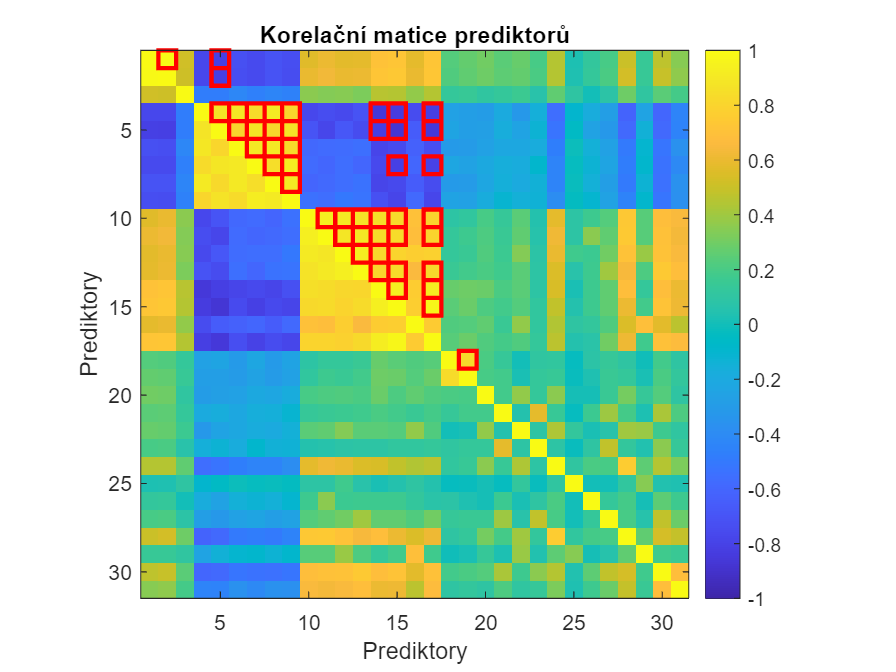

X = [ ...
    Data.EDSS, ...
    Data.Skupina, ...
    Data.Vek, ...
    Data.Rychlost.Normal, Data.Rychlost.Rychla, ...
    Data.DelkaKroku.Normal.Leva, Data.DelkaKroku.Rychla.Leva, ...
    Data.DelkaKroku.Normal.Prava, Data.DelkaKroku.Rychla.Prava, ...
    Data.CasKroku.Normal.Leva, Data.CasKroku.Rychla.Leva, ...
    Data.CasKroku.Normal.Prava, Data.CasKroku.Rychla.Prava, ...
    Data.Stoj.Normal.Leva, Data.Stoj.Rychla.Leva, ...
    Data.Stoj.Normal.Prava, Data.Stoj.Rychla.Prava, ...
    Data.SirkaBaze.Normal, Data.SirkaBaze.Rychla, ...
    Data.Variabilita.Delka.Normal.Leva, Data.Variabilita.Delka.Rychla.Leva, ...
    Data.Variabilita.Delka.Normal.Prava, Data.Variabilita.Delka.Rychla.Prava, ...
    Data.Variabilita.Cas.Normal.Leva, Data.Variabilita.Cas.Rychla.Leva, ...
    Data.Variabilita.Cas.Normal.Prava, Data.Variabilita.Cas.Rychla.Prava, ...
    Data.Variabilita.Stoj.Normal.Leva, Data.Variabilita.Stoj.Rychla.Leva, ...
    Data.Variabilita.Stoj.Normal.Prava, Data.Variabilita.Stoj.Rychla.Prava ...
];

predictorNames = { ...
    'EDSS', 'Skupina',...
    'Vek', 'Rychlost.Normal', 'Rychlost.Rychla', ...
    'DelkaKroku.Normal.Leva', 'DelkaKroku.Rychla.Leva', 'DelkaKroku.Normal.Prava', 'DelkaKroku.Rychla.Prava', ...
    'CasKroku.Normal.Leva', 'CasKroku.Rychla.Leva', 'CasKroku.Normal.Prava', 'CasKroku.Rychla.Prava', ...
    'Stoj.Normal.Leva', 'Stoj.Rychla.Leva', 'Stoj.Normal.Prava', 'Stoj.Rychla.Prava', ...
    'SirkaBaze.Normal', 'SirkaBaze.Rychla', ...
    'Variabilita.Delka.Normal.Leva', 'Variabilita.Delka.Rychla.Leva', 'Variabilita.Delka.Normal.Prava', 'Variabilita.Delka.Rychla.Prava', ...
    'Variabilita.Cas.Normal.Leva', 'Variabilita.Cas.Rychla.Leva', 'Variabilita.Cas.Normal.Prava', 'Variabilita.Cas.Rychla.Prava', ...
    'Variabilita.Stoj.Normal.Leva', 'Variabilita.Stoj.Rychla.Leva', 'Variabilita.Stoj.Normal.Prava', 'Variabilita.Stoj.Rychla.Prava'};


R = corr(X,'Rows','complete');

% Najít silně korelované páry
threshold = 0.8;
[rows, cols] = find(abs(triu(R,1)) > threshold);
toRemove = unique(cols);

% Vytvoření heatmapy
figure;
imagesc(R);
colorbar;
caxis([-1 1]); % korelace od -1 do 1
axis square;
title('Korelační matice prediktorů');
xlabel('Prediktory');
ylabel('Prediktory');

% Zvýraznění silně korelovaných párů
hold on;
for k = 1:length(rows)
    % Rámeček kolem páru (i,j)
    rectangle('Position',[cols(k)-0.5, rows(k)-0.5, 1, 1], ...
              'EdgeColor','r','LineWidth',2);
end
hold off;

% Vypsat názvy silně korelovaných párů
for k = 1:length(rows)
    fprintf('%s ↔ %s : R = %.2f\n', predictorNames{rows(k)}, predictorNames{cols(k)}, R(rows(k),cols(k)));
end

EDSS ↔ Skupina : R = 0.99
EDSS ↔ Rychlost.Rychla : R = -0.81
Skupina ↔ Rychlost.Rychla : R = -0.81
Rychlost.Normal ↔ Rychlost.Rychla : R = 0.88
Rychlost.Normal ↔ DelkaKroku.Normal.Leva : R = 0.90
Rychlost.Rychla ↔ DelkaKroku.Normal.Leva : R = 0.81
Rychlost.Normal ↔ DelkaKroku.Rychla.Leva : R = 0.83
Rychlost.Rychla ↔ DelkaKroku.Rychla.Leva : R = 0.89
DelkaKroku.Normal.Leva ↔ DelkaKroku.Rychla.Leva : R = 0.90
Rychlost.Normal ↔ DelkaKroku.Normal.Prava : R = 0.91
Rychlost.Rychla ↔ DelkaKroku.Normal.Prava : R = 0.82
DelkaKroku.Normal.Leva ↔ DelkaKroku.Normal.Prava : R = 0.90
DelkaKroku.Rychla.Leva ↔ DelkaKroku.Normal.Prava : R = 0.85
Rychlost.Normal ↔ DelkaKroku.Rychla.Prava : R = 0.81
Rychlost.Rychla ↔ DelkaKroku.Rychla.Prava : R = 0.87
DelkaKroku.Normal.Leva ↔ DelkaKroku.Rychla.Prava : R = 0.83
DelkaKroku.Rychla.Leva ↔ DelkaKroku.Rychla.Prava : R = 0.93
DelkaKroku.Normal.Prava ↔ DelkaKroku.Rychla.Prava : R = 0.91
CasKroku.Normal.Leva ↔ CasKroku.Rychla.Leva : R = 0.94
CasKroku.Normal.Leva 

# **Vendula: ROZDÍL MEZI LEVOU A PRAVOU NOHOU NAPŘÍČ PROMĚNNÝMI VS. SKUPINAMI**

**H0: s narůstajícím postižením roste asymetrie mezi levou a pravou nohou**

**HA: asymetrie mezi pravou a levou nohou je napříč paramtery stejná - nezhoršuje se s vyšším postižením**

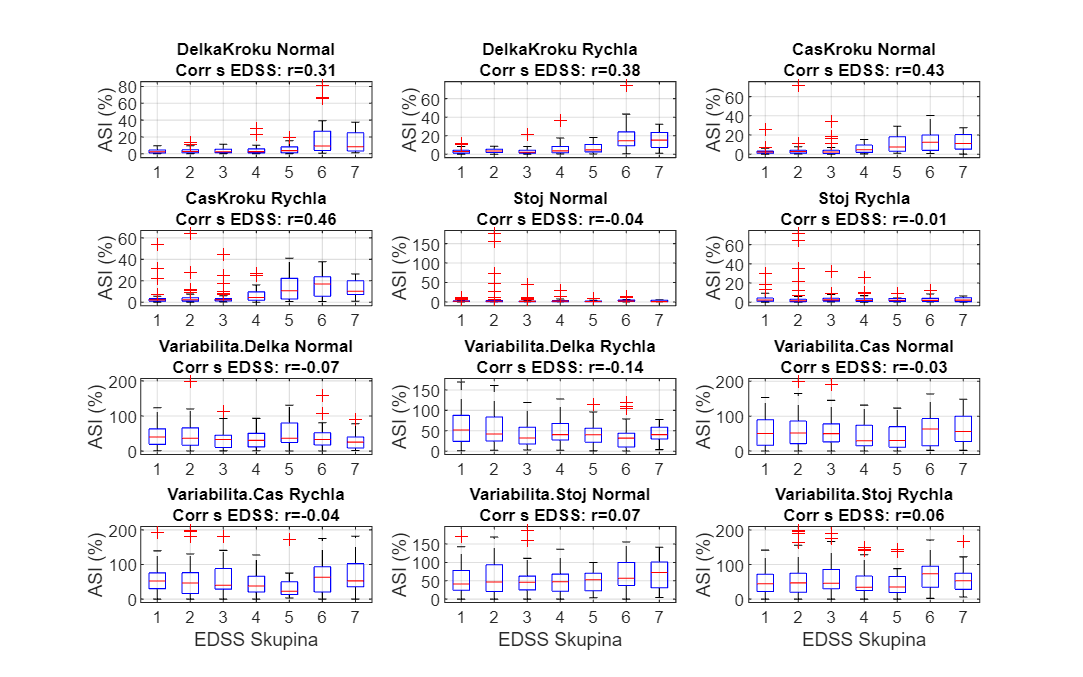

variables = {
    'DelkaKroku', 'Normal'; 'DelkaKroku', 'Rychla';
    'CasKroku', 'Normal'; 'CasKroku', 'Rychla';
    'Stoj', 'Normal'; 'Stoj', 'Rychla';
    'Variabilita.Delka', 'Normal'; 'Variabilita.Delka', 'Rychla';
    'Variabilita.Cas', 'Normal'; 'Variabilita.Cas', 'Rychla';
    'Variabilita.Stoj', 'Normal'; 'Variabilita.Stoj', 'Rychla'
};

asymmetryResults = table();
groups = unique(Data.Skupina);
figure('Name', 'Analýza asymetrie: Vztah k EDSS', 'Units', 'normalized', 'Position', [0.1 0.1 0.8 0.8]);

for i = 1:size(variables,1)
    varname = variables{i,1};
    condition = variables{i,2};
    displayName = [varname ' ' condition];

    L = eval(['Data.' varname '.' condition '.Leva']);
    P = eval(['Data.' varname '.' condition '.Prava']);

    DIFF = L-P;
 
    ASI = abs(L - P) ./ (0.5 * (L + P)) * 100;
    
    [R_rho, p_rho] = corr(ASI, Data.EDSS, 'Type', 'Spearman', 'Rows', 'complete');

    for g = 1:length(groups)
        grp = groups(g);
        idx = (Data.Skupina == grp);
        
        if sum(idx) > 0
            p_paired = signrank(L(idx), P(idx));
            
            newRow = table({displayName}, grp, median(ASI(idx), 'omitnan'), p_paired, R_rho, p_rho, ...
                'VariableNames', {'Parametr', 'EDSS_Skupina', 'Median_ASI_pct', 'p_Parovy_Test', 'Spearman_R', 'Spearman_p'});
            asymmetryResults = [asymmetryResults; newRow];
        end
    end
    subplot(4, 3, i)
    boxplot(ASI, Data.Skupina, 'Symbol', 'r+'); 
    
    title(sprintf('%s\nCorr s EDSS: r=%.2f', displayName, R_rho), 'FontSize', 8);
    ylabel('ASI (%)');
    grid on;
    
    if i <= 9, xlabel(''); else, xlabel('EDSS Skupina'); end
end

disp(asymmetryResults);

              Parametr              EDSS_Skupina    Median_ASI_pct    p_Parovy_Test    Spearman_R    Spearman_p
    ____________________________    ____________    ______________    _____________    __________    __________

    {'DelkaKroku Normal'       }         1              2.4712          0.0053213          0.3109    8.3731e-08
    {'DelkaKroku Normal'       }         2              2.6896             0.8321          0.3109    8.3731e-08
    {'DelkaKroku Normal'       }         3              2.4411            0.19015          0.3109    8.3731e-08
    {'DelkaKroku Normal'       }         4               2.564            0.49892          0.3109    8.3731e-08
    {'DelkaKroku Normal'       }         5              3.7274            0.39053          0.3109    8.3731e-08
    {'Delka

significant = asymmetryResults(asymmetryResults.p_Parovy_Test < 0.05, :)

significant = 18×6 table
             Parametr              EDSS_Skupina    Median_ASI_pct    p_Parovy_Test    Spearman_R    Spearman_p
    ___________________________    ____________    ______________    _____________    __________    __________

    {'DelkaKroku Normal'      }         1              2.4712          0.0053213         0.3109     8.3731e-08
    {'Stoj Normal'            }         2              1.5508          0.0037122      -0.035194        0.55405
    {'Stoj Normal'            }         3              1.3947           0.030845      -0.035194        0.55405
    {'Variabilita.Cas Normal' }         3                  50           0.022606      -0.027293        0.64636
    {'Variabilita.Cas Normal' }         4               29.63           0.010614      -0.027293        0

#### **UŽ OD NEJLEHČÍ FORMY RS JDE VIDĚT VÝZNAMNÝ ROZDÍL MEZI PRAVOU A LEVOU NOHOU U VARIABILITA STOJ RYCHLÁ CHŮZE (levá má větší variabilitu než pravá), ale nic není závislé na skupině :( hypotéza, že čím větší postižení, tím větší rozdíl mezi pravou a levou nohou je vyvrácena**

**-> můžu zanedbat rozdíl mezi levou a pravou brát průměr a do analýzy si dát třeba jen asymetrii ve variabilita**

% Inicializace tabulky pro stranovou dominanci
sideDominance = table();

fprintf('\n--- ANALÝZA STRANOVÉ DOMINANCE (Která noha je horší?) ---\n');


--- ANALÝZA STRANOVÉ DOMINANCE (Která noha je horší?) ---



for i = 1:size(variables, 1)
    varname = variables{i,1};
    condition = variables{i,2};
    
    L = eval(['Data.' varname '.' condition '.Leva']);
    P = eval(['Data.' varname '.' condition '.Prava']);
    
    % Definice "horšího" výkonu na základě typu parametru
    if contains(varname, 'DelkaKroku')
        % U délky je horší MENŠÍ hodnota
        isLeftWorse = L < P;
        isRightWorse = P < L;
    elseif contains(varname, 'CasKroku') || contains(varname, 'Stoj') || contains(varname, 'Variabilita')
        % U času, stoje a variability je horší VĚTŠÍ hodnota
        isLeftWorse = L > P;
        isRightWorse = P > L;
    end
    
    % Výpočet procentuálního zastoupení
    pctLeftWorse = mean(isLeftWorse, 'omitnan') * 100;
    pctRightWorse = mean(isRightWorse, 'omitnan') * 100;
    
    % Celková signifikance stranového rozdílu (Wilcoxon pro celý soubor)
    p_global = signrank(L, P);
    
    newRow = table({[varname ' ' condition]}, pctLeftWorse, pctRightWorse, p_global, ...
        'VariableNames', {'Parametr', 'Leva_Worse_pct', 'Prava_Worse_pct', 'p_Signifikance'});
    sideDominance = [sideDominance; newRow];
end

% Seřazení podle největšího rozdílu mezi stranami
disp(sideDominance);

              Parametr              Leva_Worse_pct    Prava_Worse_pct    p_Signifikance
    ____________________________    ______________    _______________    ______________

    {'DelkaKroku Normal'       }        44.912            54.737              0.17031  
    {'DelkaKroku Rychla'       }        46.667            53.333               0.1595  
    {'CasKroku Normal'         }        45.263            53.333              0.35881  
    {'CasKroku Rychla'         }        47.719            50.175               0.9932  
    {'Stoj Normal'             }        44.561            50.526              0.25226  
    {'Stoj Rychla'             }        44.912             51.93              0.35572  
    {'Variabilita.Delka Normal'}        50.175            49.825              0.40728  
    {'Variabilita.Delka Rychla'}        51.579            48.421       

# **MODELOVÁNÍ: jaké proměnné lze použít pro modelování EDSS**

- **věk je zřejmě kovariát, protože čím starší člověk je, tím hůře se hýbe bez ohledu na to, jestli je nemocná RS**

simpleVars = {
    'Vek', 'Věk';
    'Rychlost.Normal', 'Rychlost (N)';
    'Rychlost.Rychla', 'Rychlost (R)';
    'SirkaBaze.Normal', 'Šířka báze (N)';
    'SirkaBaze.Rychla', 'Šířka báze (R)'
};

pairedParams = {
    'DelkaKroku', 'Normal', 'Délka kroku (N)';
    'DelkaKroku', 'Rychla', 'Délka kroku (R)';
    'CasKroku', 'Normal', 'Čas kroku (N)';
    'CasKroku', 'Rychla', 'Čas kroku (R)';
    'Stoj', 'Normal', 'Stoj (N)';
    'Stoj', 'Rychla', 'Stoj (R)';
    'Variabilita.Delka', 'Normal', 'Var. délky (N)';
    'Variabilita.Delka', 'Rychla', 'Var. délky (R)';
    'Variabilita.Cas', 'Normal', 'Var. času (N)';
    'Variabilita.Cas', 'Rychla', 'Var. času (R)';
    'Variabilita.Stoj', 'Normal', 'Var. stoje (N)';
    'Variabilita.Stoj', 'Rychla', 'Var. stoje (R)'
};

predictorMatrix = [];
predictorNames = {};

for i = 1:size(simpleVars, 1)
    val = eval(['Data.' simpleVars{i,1}]);
    predictorMatrix(:, end+1) = val;
    predictorNames{end+1} = simpleVars{i,2};
end

for i = 1:size(pairedParams, 1)
    field = pairedParams{i,1};
    cond = pairedParams{i,2};
    label = pairedParams{i,3};
    
    L = eval(['Data.' field '.' cond '.Leva']);
    P = eval(['Data.' field '.' cond '.Prava']);

    AVG = (L + P) / 2;
    predictorMatrix(:, end+1) = AVG;
    predictorNames{end+1} = [label ' - Průměr'];

    ASI = abs(L - P) ./ (0.5 * (L + P)) * 100;
    predictorMatrix(:, end+1) = ASI;
    predictorNames{end+1} = [label ' - Asymetrie (%)'];
end

rho_vals = zeros(size(predictorMatrix, 2), 1);
p_corr_vals = zeros(size(predictorMatrix, 2), 1);
eta2_vals = zeros(size(predictorMatrix, 2), 1);
p_kw_vals = zeros(size(predictorMatrix, 2), 1);

groups = Data.EDSS;

for i = 1:size(predictorMatrix, 2)
    currentData = predictorMatrix(:, i);

    valid = ~isnan(currentData) & ~isnan(groups);
    x = currentData(valid);
    g = groups(valid);

    [r, pc] = corr(x, g, 'Type', 'Spearman');
    rho_vals(i) = r;
    p_corr_vals(i) = pc;

    [p_kw, tbl] = kruskalwallis(x, g, 'off');
    chi2 = tbl{2,5};
    N = length(x);
    k = length(unique(g));

    h2 = (chi2 - k + 1) / (N - k);
    eta2_vals(i) = max(0, h2);
    p_kw_vals(i) = p_kw;
end

finalStatsTable = table(predictorNames', rho_vals, p_corr_vals, eta2_vals, p_kw_vals, ...
    'VariableNames', {'Parametr', 'Spearman_Rho', 'p_Korelace', 'Eta_Squared', 'p_KruskalWallis'});

finalStatsTable = sortrows(finalStatsTable, 'Eta_Squared', 'descend');

disp('--- KOMPLEXNÍ ANALÝZA: Korelace a Rozdíly mezi skupinami ---');

--- KOMPLEXNÍ ANALÝZA: Korelace a Rozdíly mezi skupinami ---


disp(finalStatsTable);

                 Parametr                  Spearman_Rho    p_Korelace    Eta_Squared    p_KruskalWallis
    ___________________________________    ____________    __________    ___________    _______________

    {'Rychlost (R)'                   }       -0.75552     6.5373e-54       0.61315       2.2038e-32   
    {'Délka kroku (R) - Průměr'       }       -0.71914     1.1895e-46       0.56777       7.8366e-30   
    {'Stoj (R) - Průměr'              }        0.70332     7.6659e-44       0.54103       2.4686e-28   
    {'Rychlost (N)'                   }       -0.68677     4.2725e-41       0.52238       2.7237e-27   
    {'Délka kroku (N) - Průměr'       }       -0.68687     4.1072e-41       0.50577       2.3016e-26   
    {'Stoj (N) - Průměr'              }        0.67858     8.3658e-40       0.49337       1.1292e-25 

fprintf('--- KROK 1: Filtrace parametrů pomocí ANCOVA (očištění o věk) ---\n');

--- KROK 1: Filtrace parametrů pomocí ANCOVA (očištění o věk) ---



covariate = Data.Vek;
significantPredictorIdx = [];

for i = 2:size(predictorMatrix, 2)
    dependentVar = predictorMatrix(:, i);
    
    tblAncova = table(dependentVar, categorical(Data.Skupina), covariate, ...
        'VariableNames', {'Y', 'Group', 'Age'});
    
    try
        mdlAncova = fitlm(tblAncova, 'Y ~ Age + Group');
        anovatbl = anova(mdlAncova);
        p_Group = anovatbl.pValue(2);
        
        if p_Group < 0.05
            significantPredictorIdx = [significantPredictorIdx, i];
        end
    catch
        continue;
    end
end

X = predictorMatrix(:, significantPredictorIdx);
y = Data.EDSS;
filteredNames = predictorNames(significantPredictorIdx);

fprintf('--- KROK 2: LASSO regrese na %d signifikantních parametrech ---\n', length(significantPredictorIdx));

--- KROK 2: LASSO regrese na 8 signifikantních parametrech ---


%X = predictorMatrix(:, 2:end); 
%filteredNames = predictorNames(2:end);

[B, FitInfo] = lasso(X, y, 'CV', 10, 'PredictorNames', filteredNames, 'Standardize', true);
idxLambda = FitInfo.IndexMinMSE;
bestWeights = B(:, idxLambda);
intercept = FitInfo.Intercept(idxLambda);
activeIdx = find(bestWeights ~= 0);
lassoResults = table(filteredNames(activeIdx)', bestWeights(activeIdx), ...
    'VariableNames', {'Parametr', 'Koeficient'});
lassoResults = sortrows(lassoResults, 'Koeficient', 'descend', 'ComparisonMethod', 'abs');
y_pred = X * bestWeights + intercept;
R2 = 1 - sum((y - y_pred).^2) / sum((y - mean(y)).^2);
disp('--- FINÁLNÍ PARAMETRY VYBRANÉ LASSO MODELEM ---');

--- FINÁLNÍ PARAMETRY VYBRANÉ LASSO MODELEM ---


disp(lassoResults);

              Parametr              Koeficient
    ____________________________    __________

    {'Čas kroku (N) - Průměr'  }      -0.70565
    {'Stoj (N) - Průměr'       }      0.021874
    {'Rychlost (R)'            }     -0.019148
    {'Rychlost (N)'            }     -0.011591
    {'Délka kroku (R) - Průměr'}    -0.0084738
    {'Stoj (N) - Asymetrie (%)'}     -0.001845



fprintf('Upravené R^2 modelu: %.3f\n', R2);

Upravené R^2 modelu: 0.673


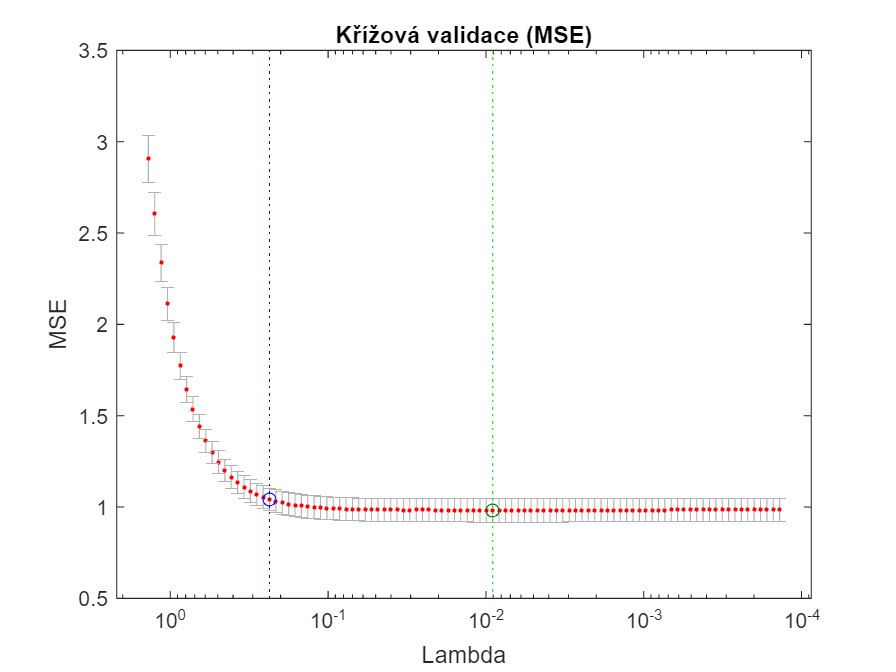

lassoPlot(B, FitInfo, 'PlotType', 'CV');
title('Křížová validace (MSE)');

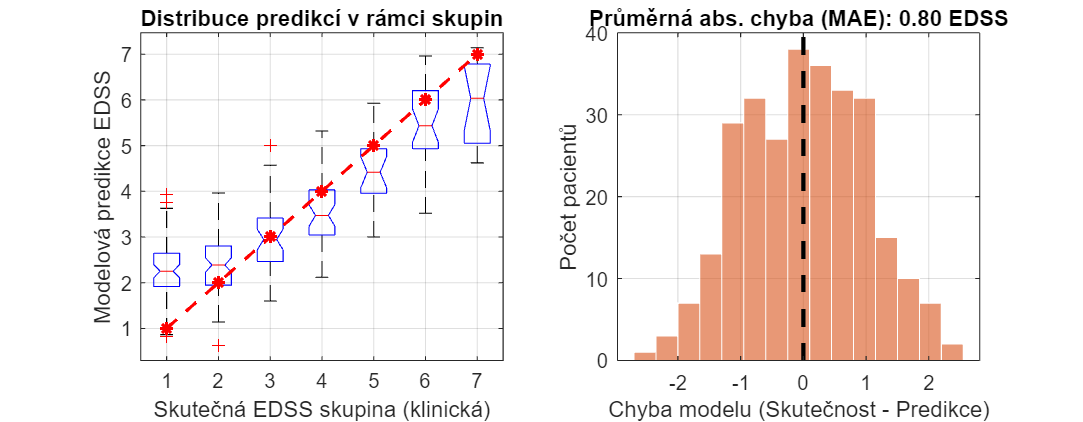

y_pred = X * bestWeights + intercept;
y_real = Data.EDSS;
rezidua = y_real - y_pred;

figure('Name', 'Validace modelu: Predikce vs Realita', 'Units', 'normalized', 'Position', [0.1 0.1 0.8 0.5]);

subplot(1,2,1);
boxplot(y_pred, Data.Skupina, 'Notch', 'on');
hold on;
unique_grps = unique(Data.Skupina);
plot(1:length(unique_grps), unique_grps, 'r*--', 'LineWidth', 1.5);
grid on;
xlabel('Skutečná EDSS skupina (klinická)');
ylabel('Modelová predikce EDSS');
title('Distribuce predikcí v rámci skupin');
subplot(1,2,2);
histogram(rezidua, 15, 'FaceColor', [0.85 0.33 0.1], 'EdgeColor', 'w');
line([0 0], ylim, 'Color', 'k', 'LineWidth', 2, 'LineStyle', '--');
xlabel('Chyba modelu (Skutečnost - Predikce)');
ylabel('Počet pacientů');
title(['Průměrná abs. chyba (MAE): ', num2str(mean(abs(rezidua)), '%.2f'), ' EDSS']);
grid on;

fprintf('\n--- PŘESNOST MODELU PODLE SKUPIN ---\n');


--- PŘESNOST MODELU PODLE SKUPIN ---


for i = 1:length(unique_grps)
    idx = (Data.Skupina == unique_grps(i));
    mae_grp = mean(abs(rezidua(idx)));
    fprintf('Skupina EDSS %.1f: Průměrná chyba %.2f\n', unique_grps(i), mae_grp);
end

Skupina EDSS 1.0: Průměrná chyba 1.05
Skupina EDSS 2.0: Průměrná chyba 0.58
Skupina EDSS 3.0: Průměrná chyba 0.68
Skupina EDSS 4.0: Průměrná chyba 0.81
Skupina EDSS 5.0: Průměrná chyba 0.93
Skupina EDSS 6.0: Průměrná chyba 0.88
Skupina EDSS 7.0: Průměrná chyba 0.82



activeIdx = find(bestWeights ~= 0);
names = filteredNames(activeIdx);
weights = bestWeights(activeIdx);

equationStr = sprintf('EDSS = %.4f', intercept);

for i = 1:length(weights)
    if weights(i) >= 0
        signStr = ' + ';
    else
        signStr = ' - ';
    end
    equationStr = [equationStr, sprintf('%s(%.4f * %s)', signStr, abs(weights(i)), names{i})];
end

fprintf('\n--- FINÁLNÍ PREDIKČNÍ ROVNICE MODELU ---\n');


--- FINÁLNÍ PREDIKČNÍ ROVNICE MODELU ---


disp(equationStr);

EDSS = 7.7247 - (0.0116 * Rychlost (N)) - (0.0191 * Rychlost (R)) - (0.0085 * Délka kroku (R) - Průměr) - (0.7056 * Čas kroku (N) - Průměr) + (0.0219 * Stoj (N) - Průměr) - (0.0018 * Stoj (N) - Asymetrie (%))


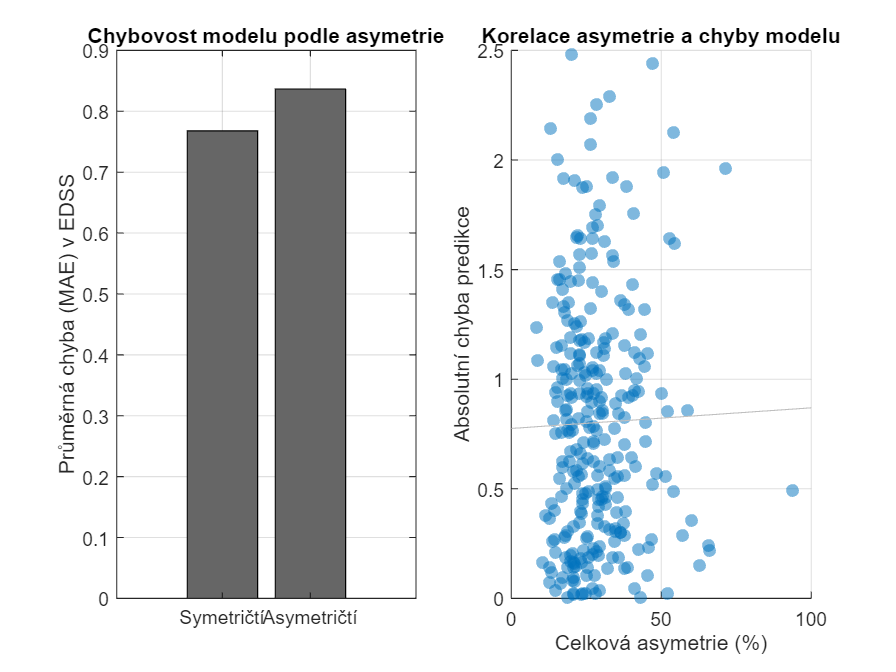


asym_indices = contains(predictorNames, 'Asymetrie');
mean_asymmetry = mean(predictorMatrix(:, asym_indices), 2);
med_asym = median(mean_asymmetry);
idx_sym = mean_asymmetry <= med_asym;
idx_asym = mean_asymmetry > med_asym;
mae_sym = mean(abs(y_real(idx_sym) - y_pred(idx_sym)));
mae_asym = mean(abs(y_real(idx_asym) - y_pred(idx_asym)));

figure('Name', 'Vliv asymetrie na přesnost predikce', 'Color', 'w');
subplot(1,2,1);
bar([mae_sym, mae_asym], 'FaceColor', [0.4 0.4 0.4]);
set(gca, 'XTickLabel', {'Symetričtí', 'Asymetričtí'});
ylabel('Průměrná chyba (MAE) v EDSS');
title('Chybovost modelu podle asymetrie');
grid on;
subplot(1,2,2);
scatter(mean_asymmetry, abs(y_real - y_pred), 'filled', 'MarkerFaceAlpha', 0.5);
hold on;
lsline;
xlabel('Celková asymetrie (%)');
ylabel('Absolutní chyba predikce');
title('Korelace asymetrie a chyby modelu');
grid on;

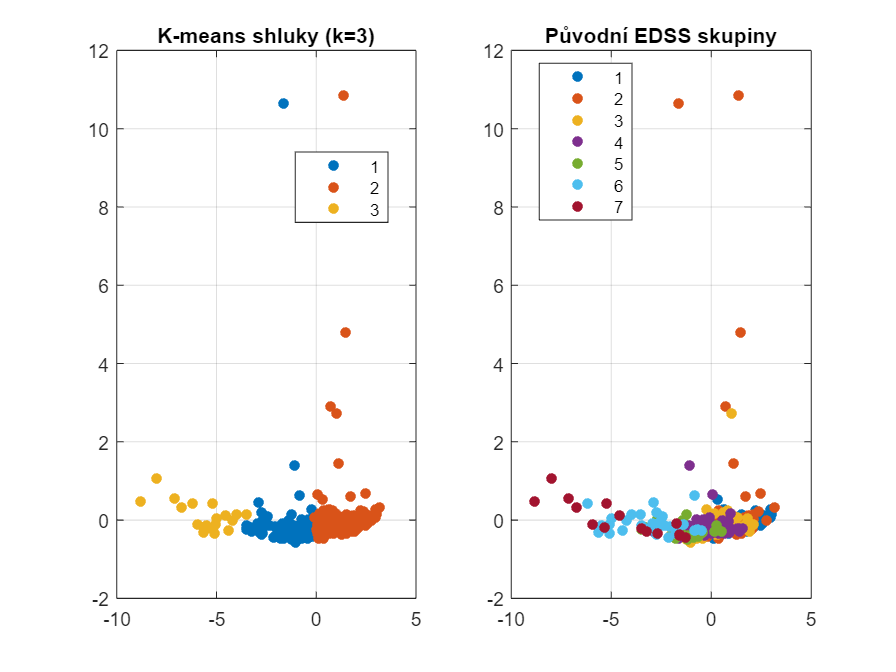

X_final = X(:, activeIdx); 
X_std = zscore(X_final);

k = 3; 
[idx, C] = kmeans(X_std, k, 'Distance', 'sqeuclidean', 'Replicates', 20);

[coeff, score] = pca(X_std);

figure('Name', 'K-means z modelovaných parametrů');
subplot(1,2,1);
gscatter(score(:,1), score(:,2), idx);
title(['K-means shluky (k=' num2str(k) ')']);
grid on;

subplot(1,2,2);
gscatter(score(:,1), score(:,2), Data.Skupina);
title('Původní EDSS skupiny');
grid on;

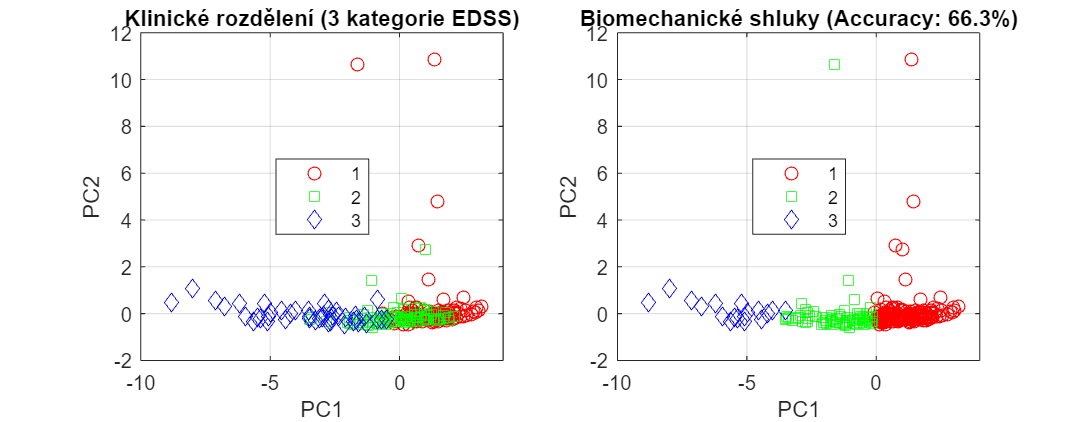

original_EDSS_3cat = zeros(size(Data.Skupina));
original_EDSS_3cat(Data.Skupina <= 2) = 1;
original_EDSS_3cat(Data.Skupina >= 3 & Data.Skupina <= 5) = 2;
original_EDSS_3cat(Data.Skupina >= 6) = 3;

confMat_3cat = confusionmat(original_EDSS_3cat, idx);

perm = nchoosek(1:3, 3);
p = perms(1:3);
best_acc = 0;
best_idx = idx;

for i = 1:size(p, 1)
    temp_idx = zeros(size(idx));
    for j = 1:3
        temp_idx(idx == j) = p(i, j);
    end
    acc = sum(original_EDSS_3cat == temp_idx) / length(temp_idx);
    if acc > best_acc
        best_acc = acc;
        best_idx = temp_idx;
    end
end

figure('Name', 'Srovnání: Klinické 3 skupiny vs. Biomechanické 3 shluky', 'Units', 'normalized', 'Position', [0.1 0.1 0.8 0.5]);

subplot(1,2,1);
gscatter(score(:,1), score(:,2), original_EDSS_3cat, 'rgb', 'osd');
title('Klinické rozdělení (3 kategorie EDSS)');
xlabel('PC1'); ylabel('PC2'); grid on;

subplot(1,2,2);
gscatter(score(:,1), score(:,2), best_idx, 'rgb', 'osd');
title(['Biomechanické shluky (Accuracy: ', num2str(best_acc*100, '%.1f'), '%)']);
xlabel('PC1'); ylabel('PC2'); grid on;


fprintf('Celková shoda po rozdělení do 3 skupin: %.2f %%\n', best_acc * 100);

Celková shoda po rozdělení do 3 skupin: 66.32 %


names_model = filteredNames(activeIdx);
[coeff, score, latent, tsquared, explained] = pca(X_std);

pcaLoadings = table(names_model', coeff(:,1), coeff(:,2), ...
    'VariableNames', {'Parametr', 'PC1_Vaha', 'PC2_Vaha'});
pcaLoadings = sortrows(pcaLoadings, 'PC1_Vaha', 'descend');

fprintf('\n--- PCA ANALÝZA: VYSVĚTLENÝ ROZPTYL ---\n');


--- PCA ANALÝZA: VYSVĚTLENÝ ROZPTYL ---


fprintf('PC1 vysvětluje: %.2f %% rozptylu\n', explained(1));

PC1 vysvětluje: 69.18 % rozptylu


fprintf('PC2 vysvětluje: %.2f %% rozptylu\n', explained(2));

PC2 vysvětluje: 17.18 % rozptylu


fprintf('Dohromady tyto dvě osy pokrývají: %.2f %% dat\n', sum(explained(1:2)));

Dohromady tyto dvě osy pokrývají: 86.37 % dat



disp('--- KOEFICIENTY (Loadings) ---');

--- KOEFICIENTY (Loadings) ---


disp(pcaLoadings);

              Parametr              PC1_Vaha      PC2_Vaha 
    ____________________________    _________    __________

    {'Rychlost (N)'            }      0.46943    -0.0039109
    {'Rychlost (R)'            }       0.4598      0.092089
    {'Délka kroku (R) - Průměr'}      0.43367        0.1313
    {'Stoj (N) - Asymetrie (%)'}    0.0085594       0.97202
    {'Čas kroku (N) - Průměr'  }     -0.41989       0.11412
    {'Stoj (N) - Průměr'       }      -0.4514       0.12815



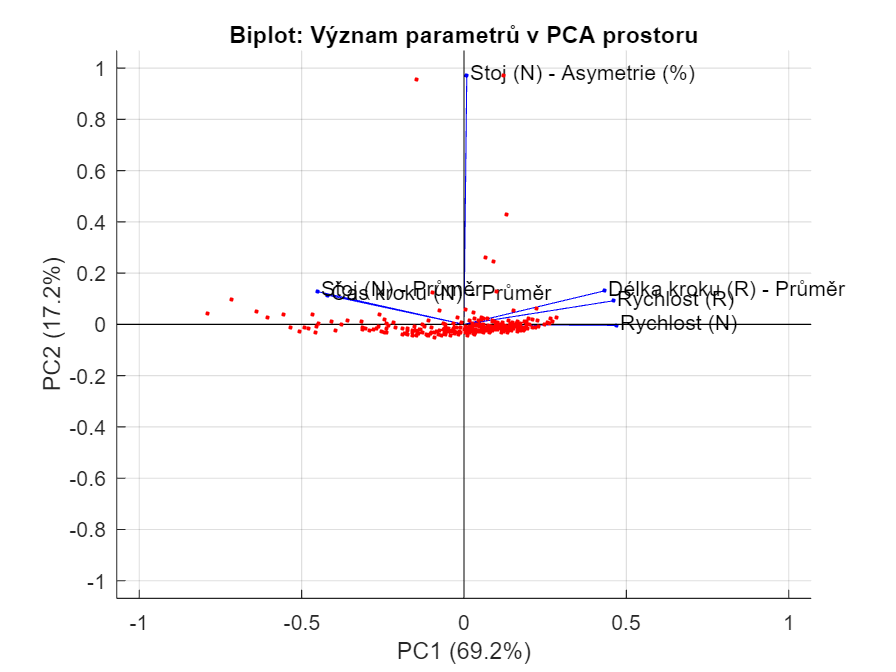

figure('Name', 'Význam parametrů v PCA prostoru');
biplot(coeff(:,1:2), 'Scores', score(:,1:2), 'VarLabels', names_model);
title('Biplot: Význam parametrů v PCA prostoru');
xlabel(['PC1 (', num2str(explained(1), '%.1f'), '%)']);
ylabel(['PC2 (', num2str(explained(2), '%.1f'), '%)']);
grid on;

% 1. Kontrola vysvětleného rozptylu pro první 3 komponenty
fprintf('První 3 komponenty vysvětlují dohromady: %.2f %% rozptylu\n', sum(explained(1:3)));

První 3 komponenty vysvětlují dohromady: 94.63 % rozptylu



% 2. Výpis Loadings pro 3 komponenty
pcaLoadings3 = table(names_model', coeff(:,1), coeff(:,2), coeff(:,3), ...
    'VariableNames', {'Parametr', 'PC1_Vaha', 'PC2_Vaha', 'PC3_Vaha'});
disp(pcaLoadings3);

              Parametr              PC1_Vaha      PC2_Vaha     PC3_Vaha
    ____________________________    _________    __________    ________

    {'Rychlost (N)'            }      0.46943    -0.0039109    0.054492
    {'Rychlost (R)'            }       0.4598      0.092089     0.30961
    {'Délka kroku (R) - Průměr'}      0.43367        0.1313      0.5733
    {'Čas kroku (N) - Průměr'  }     -0.41989       0.11412     0.65161
    {'Stoj (N) - Průměr'       }      -0.4514       0.12815     0.31244
    {'Stoj (N) - Asymetrie (%)'}    0.0085594       0.97202    -0.22425



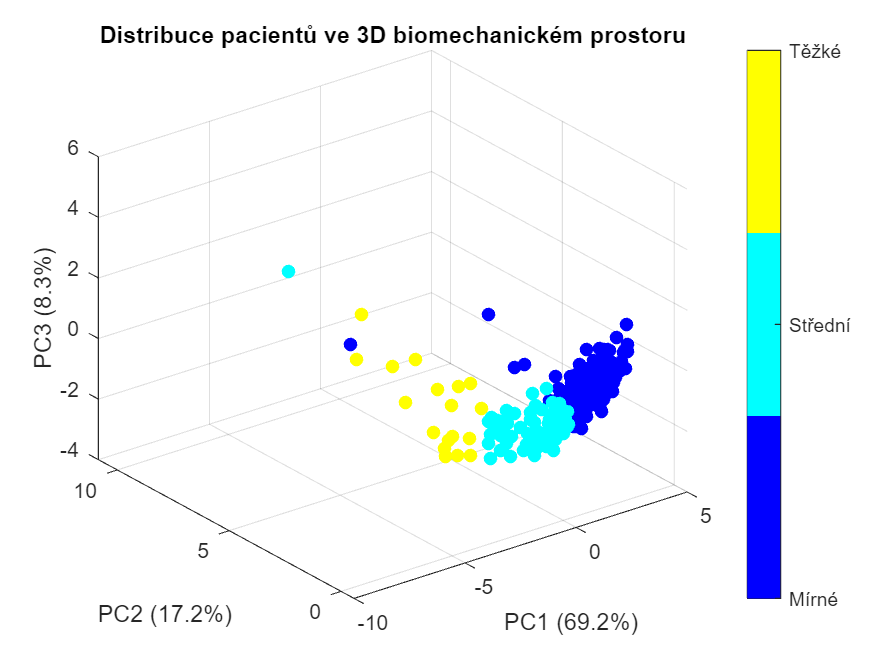


% 3. 3D Vizualizace
figure('Name', '3D PCA prostor pacientů');
scatter3(score(:,1), score(:,2), score(:,3), 40, best_idx, 'filled');
colormap(jet(3));
xlabel(['PC1 (', num2str(explained(1), '%.1f'), '%)']);
ylabel(['PC2 (', num2str(explained(2), '%.1f'), '%)']);
zlabel(['PC3 (', num2str(explained(3), '%.1f'), '%)']);
title('Distribuce pacientů ve 3D biomechanickém prostoru');
colorbar('Ticks', [1,2,3], 'TickLabels', {'Mírné', 'Střední', 'Těžké'});
grid on; rotate3d on;

# **POTŘEBUJE PACIENT UŽ OPORU?**

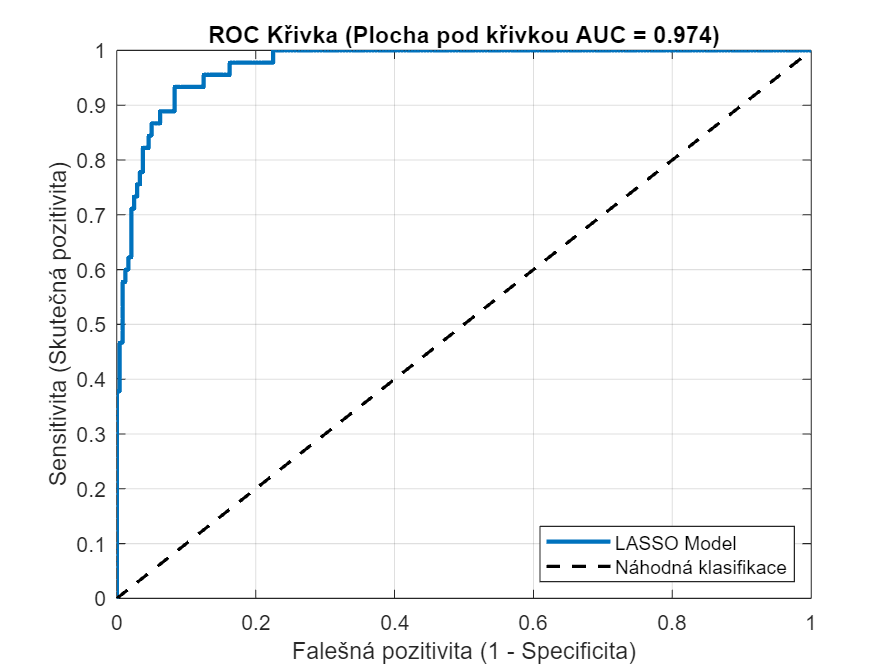

y_binary = double(Data.Skupina >= 6);
[X_roc, Y_roc, T_roc, AUC] = perfcurve(y_binary, y_pred, 1);

figure('Name', 'ROC Analýza: Detekce těžšího postižení (EDSS 6+)', 'Color', 'w');
plot(X_roc, Y_roc, 'LineWidth', 2, 'Color', [0 0.447 0.741]);
hold on;
plot([0 1], [0 1], 'k--', 'LineWidth', 1.5); 
xlabel('Falešná pozitivita (1 - Specificita)');
ylabel('Sensitivita (Skutečná pozitivita)');
title(['ROC Křivka (Plocha pod křivkou AUC = ', num2str(AUC, '%.3f'), ')']);
legend('LASSO Model', 'Náhodná klasifikace', 'Location', 'SouthEast');
grid on;


[~, optIdx] = max(Y_roc + (1 - X_roc) - 1);
optThreshold = T_roc(optIdx);
fprintf('\n--- VÝSLEDKY ROC ANALÝZY ---\n');


--- VÝSLEDKY ROC ANALÝZY ---


fprintf('Plocha pod křivkou (AUC): %.3f\n', AUC);

Plocha pod křivkou (AUC): 0.974


fprintf('Optimální dělící práh modelu: %.2f EDSS\n', optThreshold);

Optimální dělící práh modelu: 4.36 EDSS


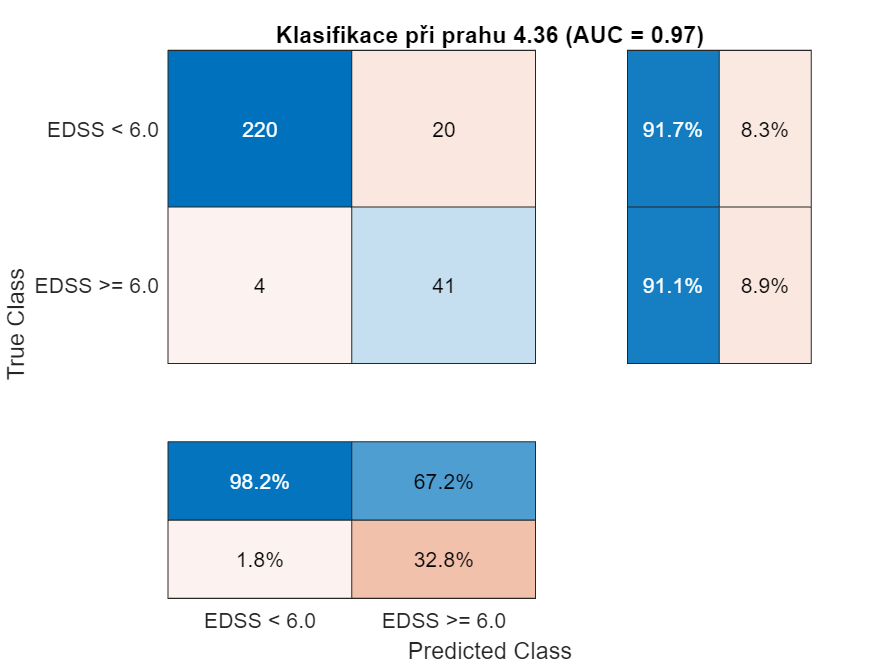

y_class_pred = double(y_pred > 4.36);
y_class_real = double(Data.Skupina >= 6);

C = confusionmat(y_class_real, y_class_pred);

figure('Name', 'Validace prahu 4.36: Confusion Matrix', 'Color', 'w');
confusionchart(C, {'EDSS < 6.0', 'EDSS >= 6.0'}, ...
    'Title', ['Klasifikace při prahu 4.36 (AUC = 0.97)'], ...
    'RowSummary', 'row-normalized', 'ColumnSummary', 'column-normalized');

TP = C(2,2); TN = C(1,1); FP = C(1,2); FN = C(2,1);
sens = TP / (TP + FN);
spec = TN / (TN + FP);
acc = (TP + TN) / sum(C(:));

fprintf('\n--- DETAILNÍ METRIKY PRO PRÁH 4.36 ---\n');


--- DETAILNÍ METRIKY PRO PRÁH 4.36 ---


fprintf('Celková přesnost (Accuracy): %.2f %%\n', acc * 100);

Celková přesnost (Accuracy): 91.58 %


fprintf('Sensitivita (Schopnost najít EDSS 6+): %.2f %%\n', sens * 100);

Sensitivita (Schopnost najít EDSS 6+): 91.11 %


fprintf('Specificita (Schopnost poznat lehčí stavy): %.2f %%\n', spec * 100);

Specificita (Schopnost poznat lehčí stavy): 91.67 %


# **NELINEÁRNÍ PROGRESE**

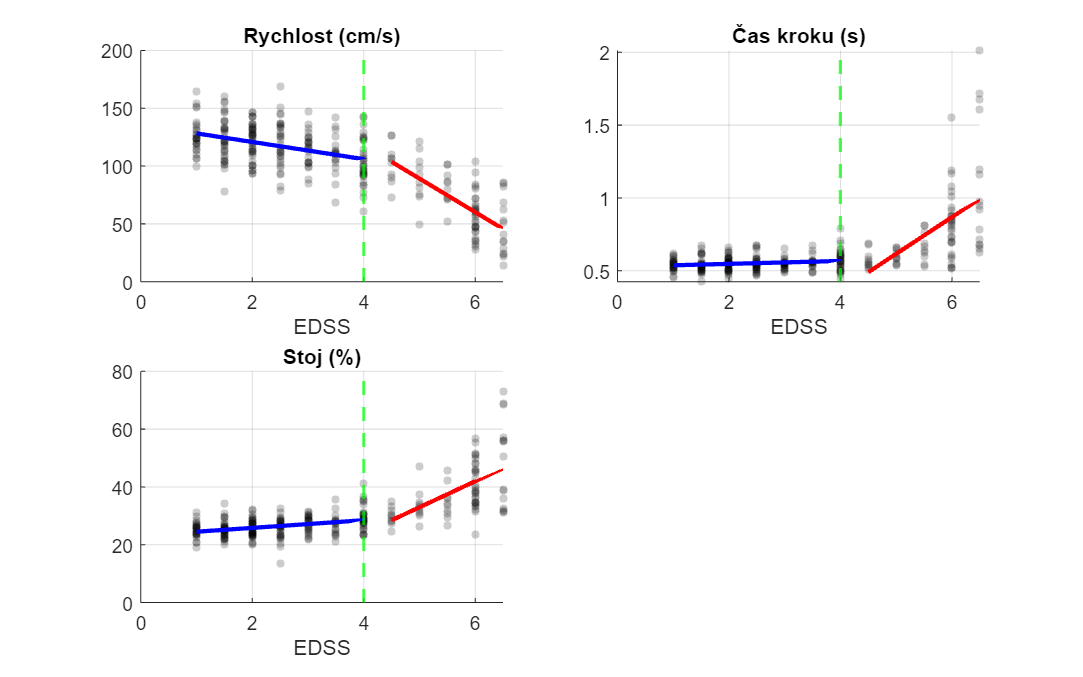

Parametr Rychlost (cm/s): Nad 4.0 je progrese 3.90x rychlejší
Parametr Čas kroku (s): Nad 4.0 je progrese 25.35x rychlejší


Parametr Stoj (%): Nad 4.0 je progrese 6.77x rychlejší


idx_low = Data.EDSS < 4.36;
idx_high = Data.EDSS >= 4.36;

params_to_test = {'Rychlost.Normal', 'CasKroku.Normal.Leva', 'Stoj.Normal.Leva'};
titles = {'Rychlost (cm/s)', 'Čas kroku (s)', 'Stoj (%)'};

figure('Name', 'Multifaktoriální analýza zlomu EDSS 4.0', 'Units', 'normalized', 'Position', [0.1 0.1 0.8 0.8]);

for i = 1:length(params_to_test)
    y_val = eval(['Data.' params_to_test{i}]);
    
    % Filtrace NaN
    valid = ~isnan(y_val) & ~isnan(Data.EDSS);
    curr_x = Data.EDSS(valid);
    curr_y = y_val(valid);
    
    % Rozdělení
    low = curr_x < 4.36;
    high = curr_x >= 4.36;
    
    % Modely
    m_low = fitlm(curr_x(low), curr_y(low));
    m_high = fitlm(curr_x(high), curr_y(high));
    
    % Grafy
    subplot(2, 2, i);
    scatter(curr_x, curr_y, 15, 'k', 'filled', 'MarkerFaceAlpha', 0.2);
    hold on;
    plot(curr_x(low), predict(m_low, curr_x(low)), 'b', 'LineWidth', 2);
    plot(curr_x(high), predict(m_high, curr_x(high)), 'r', 'LineWidth', 2);
    xline(4.0, '--g', 'LineWidth', 1.5);
    
    title(titles{i});
    grid on;
    xlabel('EDSS');
    
    % Výpis rozdílu sklonů
    diff_slope = (abs(m_high.Coefficients.Estimate(2)) / abs(m_low.Coefficients.Estimate(2)));
    fprintf('Parametr %s: Nad 4.0 je progrese %.2fx rychlejší\n', titles{i}, diff_slope);
end

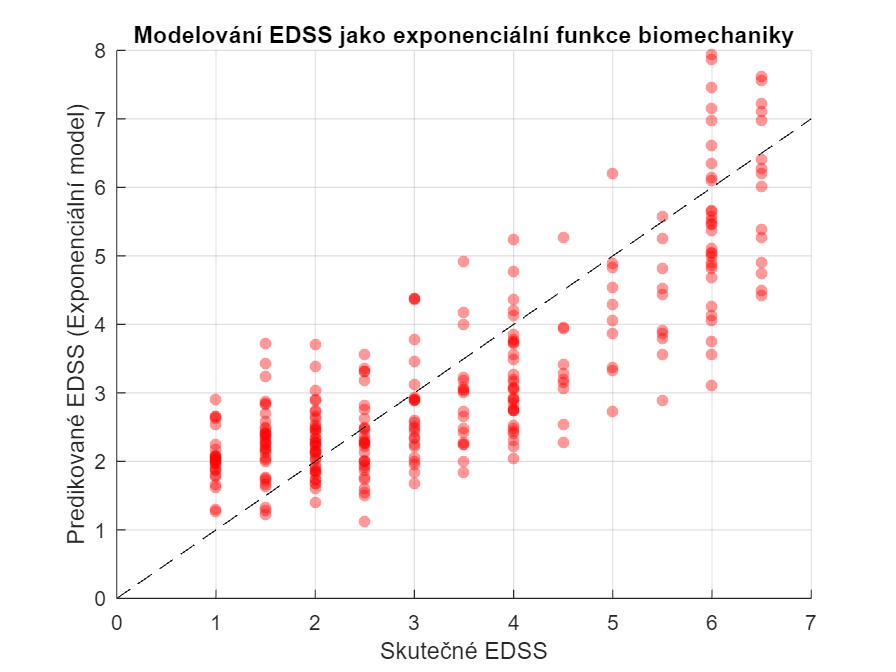

y_log = log(y + 1); 

[B_log, FitInfo_log] = lasso(X, y_log, 'CV', 10, 'Standardize', true);
idxLambdaLog = FitInfo_log.IndexMinMSE;

y_pred_log_scaled = exp(X * B_log(:, idxLambdaLog) + FitInfo_log.Intercept(idxLambdaLog)) - 1;

figure('Name', 'Exponenciální model progrese', 'Color', 'w');
scatter(y, y_pred_log_scaled, 30, 'r', 'filled', 'MarkerFaceAlpha', 0.4);
hold on;
plot([0 7], [0 7], 'k--');
xlabel('Skutečné EDSS'); ylabel('Predikované EDSS (Exponenciální model)');
title('Modelování EDSS jako exponenciální funkce biomechaniky');
grid on;

% Porovnání reziduí pro nízké a vysoké EDSS
res_low = abs(y(y < 4.36) - y_pred(y < 4.36));
res_high = abs(y(y >= 4.36) - y_pred(y >= 4.36));

fprintf('Průměrná chyba pod EDSS 4.36: %.2f\n', mean(res_low));

Průměrná chyba pod EDSS 4.36: 0.77


fprintf('Průměrná chyba nad EDSS 4.36: %.2f\n', mean(res_high));

Průměrná chyba nad EDSS 4.36: 0.90


thresholds = 2.0:0.1:5.0;
total_errors = zeros(size(thresholds));

for i = 1:length(thresholds)
    thr = thresholds(i);
    low = Data.EDSS < thr;
    high = Data.EDSS >= thr;
    mae_low = mean(abs(y(low) - y_pred(low)));
    mae_high = mean(abs(y(high) - y_pred(high)));
    total_errors(i) = (sum(low)*mae_low + sum(high)*mae_high) / length(y);
end

[minErr, optIdx] = min(total_errors);
optThreshold = thresholds(optIdx);

fprintf('Optimální bod zlomu (Breakpoint) je: %.1f EDSS\n', optThreshold);

Optimální bod zlomu (Breakpoint) je: 2.6 EDSS


y_log = log(y + 1);
[B_log, FitInfo_log] = lasso(X, y_log, 'CV', 10, 'Standardize', true);
idx_log = FitInfo_log.IndexMinMSE;
y_pred_log = exp(X * B_log(:, idx_log) + FitInfo_log.Intercept(idx_log)) - 1;
errors_new = y - y_pred_log;
fprintf('MAE u EDSS 1-2 po opravě: %.2f\n', mean(abs(errors_new(y <= 2))));

MAE u EDSS 1-2 po opravě: 0.72


fprintf('MAE u EDSS 6-7 po opravě: %.2f\n', mean(abs(errors_new(y >= 6))));% 1. Definice prahu z ROC analýzy

MAE u EDSS 6-7 po opravě: 1.08


threshold = 4.36; 

% 2. Automatické získání názvů parametrů, které vybralo LASSO
% Předpokládáme, že máš 'activeIdx' a 'filteredNames' z předchozích kroků
params_to_test = filteredNames(activeIdx);
titles = strrep(params_to_test, '_', ' '); % Hezčí názvy pro grafy

num_params = length(params_to_test);
rows = ceil(sqrt(num_params));
cols = ceil(num_params/rows);

figure('Name', ['Analýza zlomu v EDSS ' num2str(threshold)], 'Units', 'normalized', 'Position', [0.1 0.1 0.8 0.8]);

fprintf('\n--- ANALÝZA ZLOMU PROGRESE (Práh: %.2f) ---\n', threshold);


--- ANALÝZA ZLOMU PROGRESE (Práh: 4.36) ---


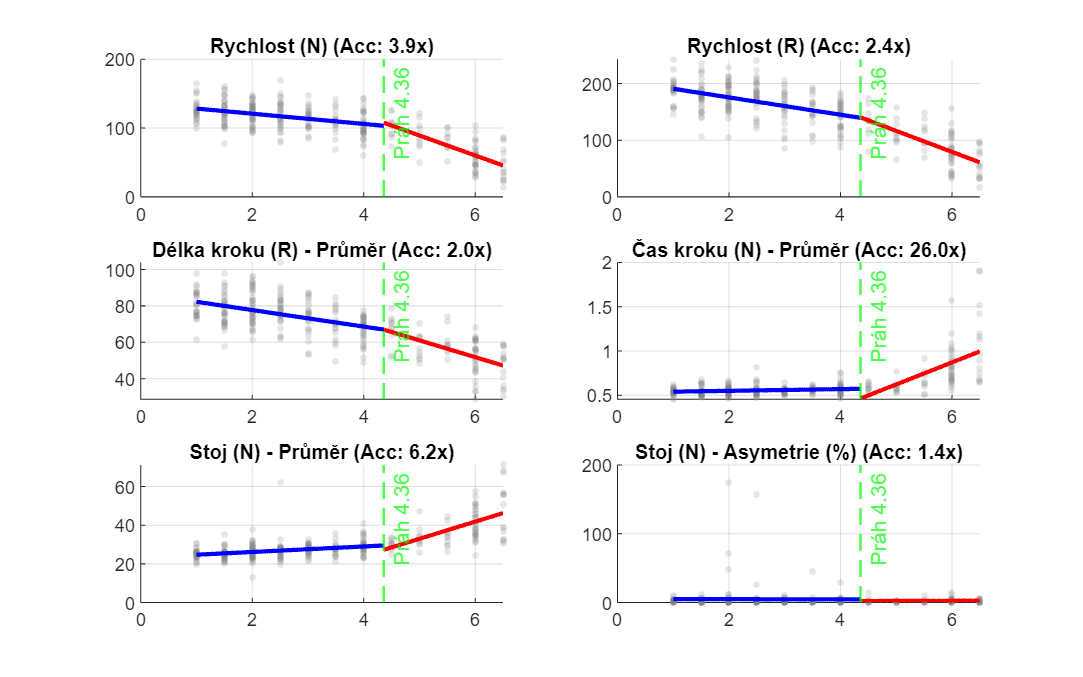

Parametr: Rychlost (N)              | Sklon pod: -7.439 | Sklon nad: -29.024 | Zrychlení:   3.9x
Parametr: Rychlost (R)              | Sklon pod: -15.275 | Sklon nad: -37.067 | Zrychlení:   2.4x
Parametr: Délka kroku (R) - Průměr  | Sklon pod: -4.548 | Sklon nad: -9.223 | Zrychlení:   2.0x
Parametr: Čas kroku (N) - Průměr    | Sklon pod:  0.010 | Sklon nad:  0.248 | Zrychlení:  26.0x
Parametr: Stoj (N) - Průměr         | Sklon pod:  1.423 | Sklon nad:  8.858 | Zrychlení:   6.2x


Parametr: Stoj (N) - Asymetrie (%)  | Sklon pod: -0.182 | Sklon nad:  0.262 | Zrychlení:   1.4x



for i = 1:num_params
    try
        y_val = Data.(params_to_test{i});
    catch
        y_val = X(:, i); 
    end
    
    valid = ~isnan(y_val) & ~isnan(Data.EDSS);
    curr_x = Data.EDSS(valid);
    curr_y = y_val(valid);

    low_mask = curr_x < threshold;
    high_mask = curr_x >= threshold;

    m_low = fitlm(curr_x(low_mask), curr_y(low_mask));
    m_high = fitlm(curr_x(high_mask), curr_y(high_mask));

    slope_low = m_low.Coefficients.Estimate(2);
    slope_high = m_high.Coefficients.Estimate(2);
    accel = abs(slope_high) / abs(slope_low);

    subplot(rows, cols, i);
    scatter(curr_x, curr_y, 10, [0.5 0.5 0.5], 'filled', 'MarkerFaceAlpha', 0.2);
    hold on;

    x_range_low = linspace(min(curr_x(low_mask)), threshold, 100);
    x_range_high = linspace(threshold, max(curr_x(high_mask)), 100);
    
    plot(x_range_low, predict(m_low, x_range_low'), 'b', 'LineWidth', 2);
    plot(x_range_high, predict(m_high, x_range_high'), 'r', 'LineWidth', 2);
    
    xline(threshold, '--g', ['Práh ' num2str(threshold)], 'LineWidth', 1.2);
    
    title(sprintf('%s (Acc: %.1fx)', titles{i}, accel));
    grid on;
    
    fprintf('Parametr: %-25s | Sklon pod: %6.3f | Sklon nad: %6.3f | Zrychlení: %5.1fx\n', ...
        params_to_test{i}, slope_low, slope_high, accel);
end

threshold = 4.36;
groupLabels = cell(size(Data.EDSS));
groupLabels(Data.EDSS < threshold) = {'Mild (under 4.36)'};
groupLabels(Data.EDSS >= threshold) = {'Severe (over 4.36)'};

statsResults = table();

fprintf('\n--- TEST SIGNIFIKANCE ROZDÍLŮ (Práh: %.2f) ---\n', threshold);


--- TEST SIGNIFIKANCE ROZDÍLŮ (Práh: 4.36) ---



for i = 1:size(predictorMatrix, 2)
    currentData = predictorMatrix(:, i);
    paramName = predictorNames{i};

    valid = ~isnan(currentData) & ~isnan(Data.EDSS);
    cleanData = currentData(valid);
    cleanGroups = groupLabels(valid);

    [p, h, stats] = ranksum(cleanData(strcmp(cleanGroups, 'Mild (under 4.36)')), ...
                             cleanData(strcmp(cleanGroups, 'Severe (over 4.36)')));

    medMild = median(cleanData(strcmp(cleanGroups, 'Mild (under 4.36)')));
    medSevere = median(cleanData(strcmp(cleanGroups, 'Severe (over 4.36)')));

    statsResults(i, :) = table({paramName}, medMild, medSevere, p, ...
        'VariableNames', {'Parametr', 'Median_Mild', 'Median_Severe', 'p_value'});
end

statsResults = sortrows(statsResults, 'p_value');

disp(statsResults(statsResults.p_value < 0.05, :));

                 Parametr                  Median_Mild    Median_Severe     p_value  
    ___________________________________    ___________    _____________    __________

    {'Rychlost (R)'                   }       173.45           93.5         1.617e-30
    {'Stoj (R) - Průměr'              }         20.7           31.8        1.2921e-28
    {'Délka kroku (R) - Průměr'       }       75.356         55.763        3.7502e-28
    {'Rychlost (N)'                   }        118.8             71        6.2145e-28
    {'Stoj (N) - Průměr'              }       26.225          35.55        3.1969e-27
    {'Délka kroku (N) - Průměr'       }       64.386         49.415        1.9287e-25
    {'Čas kroku (R) - Průměr'         }       0.4465         0.6105        1.5472e-24
    {'Var. stoje (N) - Průměr'        }      0.01625          0.043        7.6629e-23
   

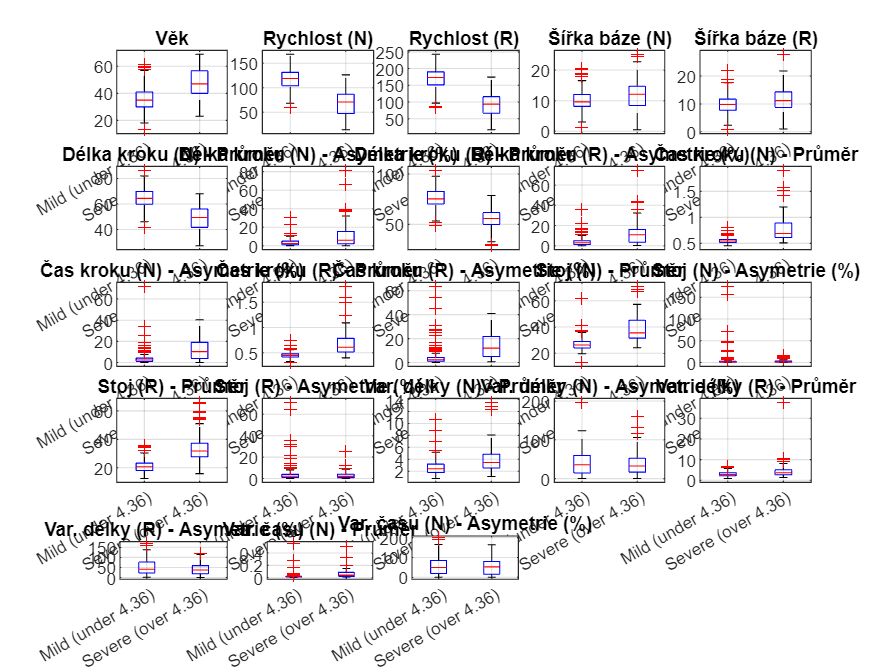


[~, topIdx] = sort(statsResults.p_value);
figure('Name', 'Rozdíly v parametrech mezi skupinami', 'Color', 'w');
for j = 1:23
    subplot(5, 5, j);
    boxplot(predictorMatrix(:, topIdx(j)), groupLabels);
    title(predictorNames{topIdx(j)});
    grid on;
end

effectResults = table();
n_total = sum(~isnan(Data.EDSS));

fprintf('\n--- ANALÝZA KLINICKÉ VÝZNAMNOSTI (Práh: %.2f) ---\n', threshold);


--- ANALÝZA KLINICKÉ VÝZNAMNOSTI (Práh: 4.36) ---



for i = 1:size(predictorMatrix, 2)
    currentData = predictorMatrix(:, i);
    paramName = predictorNames{i};
    
    valid = ~isnan(currentData) & ~isnan(Data.EDSS);
    cleanData = currentData(valid);
    cleanGroups = groupLabels(valid);
    [p, ~, stats] = ranksum(cleanData(strcmp(cleanGroups, 'Mild (under 4.36)')), ...
                             cleanData(strcmp(cleanGroups, 'Severe (over 4.36)')));
    z_val = stats.zval;
    r_val = abs(z_val) / sqrt(length(cleanData));
    medMild = median(cleanData(strcmp(cleanGroups, 'Mild (under 4.36)')));
    medSevere = median(cleanData(strcmp(cleanGroups, 'Severe (over 4.36)')));
    diff_pct = ((medSevere - medMild) / medMild) * 100;
    
    effectResults(i, :) = table({paramName}, medMild, medSevere, diff_pct, p, r_val, ...
        'VariableNames', {'Parametr', 'Mild', 'Severe', 'Zmena_pct', 'p_value', 'EffectSize_r'});
end

effectResults = sortrows(effectResults, 'EffectSize_r', 'descend');

disp(effectResults);

                 Parametr                   Mild      Severe    Zmena_pct     p_value      EffectSize_r
    ___________________________________    _______    ______    _________    __________    ____________

    {'Rychlost (R)'                   }     173.45      93.5     -46.094      1.617e-30        0.68016 
    {'Stoj (R) - Průměr'              }       20.7      31.8      53.623     1.2921e-28        0.65735 
    {'Délka kroku (R) - Průměr'       }     75.356    55.763     -26.001     3.7502e-28        0.65168 
    {'Rychlost (N)'                   }      118.8        71     -40.236     6.2145e-28        0.64898 
    {'Stoj (N) - Průměr'              }     26.225     35.55      35.558     3.1969e-27        0.64014 
    {'Délka kroku (N) - Průměr'       }     64.386    49.415     -2

%% 1. PŘÍPRAVA DAT A PRAHU
threshold = 4.36; % Práh z ROC analýzy [cite: 2115]
y = Data.EDSS;
idx_low = (y < threshold);
idx_high = (y >= threshold);

%% 2. VÝPOČET PREDIKCÍ
% A) Lineární model (standardní LASSO) [cite: 1766, 1792]
y_pred_lin = X * bestWeights + intercept;

% B) Logaritmický model (Log-LASSO) [cite: 2235, 2284]
y_pred_log = exp(X * B_log(:, idx_log) + FitInfo_log.Intercept(idx_log)) - 1;

% C) Hybridní model (Segmentový) - přepíná v bodě 4.36
y_pred_hybrid = zeros(size(y));
y_pred_hybrid(idx_low) = y_pred_log(idx_low);   % Pro lehké stavy logaritmus
y_pred_hybrid(idx_high) = y_pred_lin(idx_high); % Pro těžké stavy lineární trend

%% 3. VÝPOČET CHYB (MAE)
% Lineární MAE
mae_lin_12 = mean(abs(y(y <= 2) - y_pred_lin(y <= 2)));
mae_lin_67 = mean(abs(y(y >= 6) - y_pred_lin(y >= 6)));
mae_lin_total = mean(abs(y - y_pred_lin));

% Logaritmické MAE
mae_log_12 = mean(abs(y(y <= 2) - y_pred_log(y <= 2)));
mae_log_67 = mean(abs(y(y >= 6) - y_pred_log(y >= 6)));
mae_log_total = mean(abs(y - y_pred_log));

% Hybridní MAE
mae_hyb_12 = mean(abs(y(y <= 2) - y_pred_hybrid(y <= 2)));
mae_hyb_67 = mean(abs(y(y >= 6) - y_pred_hybrid(y >= 6)));
mae_hyb_total = mean(abs(y - y_pred_hybrid));

%% 4. ZOBRAZENÍ VÝSLEDKŮ
Model_Types = {'Linearni_LASSO'; 'Logaritmicke_LASSO'; 'Hybridni_Model'};
MAE_1_to_2 = [mae_lin_12; mae_log_12; mae_hyb_12];
MAE_6_to_7 = [mae_lin_67; mae_log_67; mae_hyb_67];
MAE_Celkove = [mae_lin_total; mae_log_total; mae_hyb_total];

comparisonTable = table(Model_Types, MAE_1_to_2, MAE_6_to_7, MAE_Celkove);
disp('--- FINÁLNÍ SROVNÁNÍ PŘESNOSTI MODELŮ ---');

--- FINÁLNÍ SROVNÁNÍ PŘESNOSTI MODELŮ ---


disp(comparisonTable);

         Model_Types          MAE_1_to_2    MAE_6_to_7    MAE_Celkove
    ______________________    __________    __________    ___________

    {'Linearni_LASSO'    }     0.86001       0.86192        0.80205  
    {'Logaritmicke_LASSO'}     0.71755        1.0779        0.83114  
    {'Hybridni_Model'    }     0.71755       0.86192        0.77278  



function boxplotByGroup(values, group, titleText, yLabel)

    valid = ~isnan(values) & ~isnan(group);
    [p, ~, ~] = kruskalwallis(values(valid), group(valid), 'off');
    figure
    boxplot(values(valid), group(valid))

    if p < 0.05
        title(sprintf('%s (Kruskal–Wallis p = %.3g < 0.05 => H0 lze zamítnout)', titleText, p), ...
          'Interpreter','none')
    else
        title(sprintf('%s (Kruskal–Wallis p = %.3g > 0.05 => H0 nelze zamítnout)', titleText, p), ...
          'Interpreter','none')
    end
    xlabel('Skupina')
    ylabel(yLabel)
    grid on
end